%%NoAP1903
ydata1 =  [0.994351247	0.9916548	0.989389418	0.996206878	0.994587755	0.983118519	0.893697128	0.400989342	0.006447241	0.00148715];
%%NoBlast
ydata2 =  [0.020884656	0.038708919	0.053608692	0.0795322	0.106651625	0.426742328	0.801811791	0.927911111	0.978334618	0.916049206];
%%Both
ydata3 =  [0.028152532	0.050824187	0.055106803	0.078311489	0.12464966	0.216782237	0.052270824	0.020610733	0.004709373	0.000569237];


Y0 = 0.05; K = 1; t=72;

rdata = revLogest([ydata1; ydata2; ydata3], Y0, K, t)

rdata =     0.1127    0.1073    0.1039    0.1183    0.1133    0.0973    0.0705    0.0353   -0.0291   -0.0495
   -0.0125   -0.0037    0.0010    0.0069    0.0114    0.0368    0.0603    0.0764    0.0938    0.0741
   -0.0083    0.0002    0.0014    0.0067    0.0138    0.0231    0.0007   -0.0127   -0.0335   -0.0629


rdata(1, :) + rdata(2, :) - max(max(rdata))

ans =    -0.0181   -0.0147   -0.0134    0.0069    0.0064    0.0159    0.0125   -0.0066   -0.0535   -0.0937


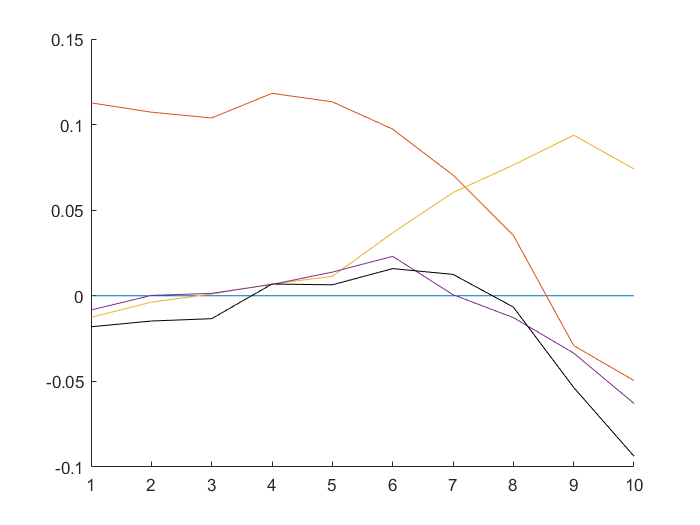

fig = figure(1); clf(fig)
hold on;
plot([1, 10], [0, 0]);
plot(rdata');
plot(rdata(1, :) + rdata(2, :) - max(max(rdata)), 'color', [0, 0, 0]);
hold off;